# Assignment 3 : submission (Kunal Sagar)

### Problem 1:

#### a)

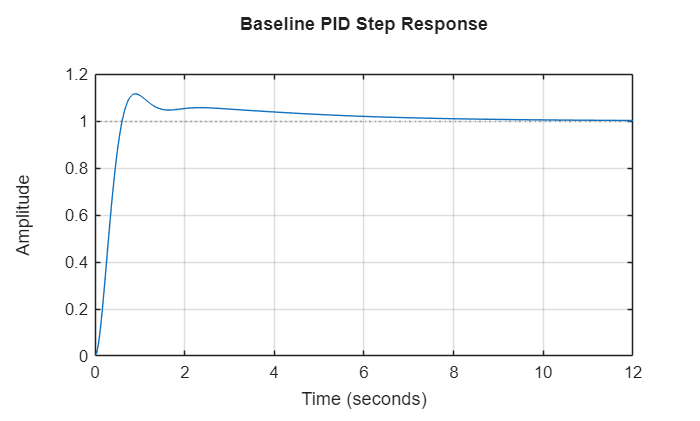

s = tf('s');
G = 20 / (s*(s+2)*(s+5));

C_pid = pidtune(G, 'PID');

T_pid = feedback(C_pid * G, 1);

figure;
step(T_pid);
title('Baseline PID Step Response');
grid on;


info_pid = stepinfo(T_pid);
fprintf('PID Rise Time: %.3f s\n', info_pid.RiseTime);

PID Rise Time: 0.408 s


fprintf('PID Settling Time: %.3f s\n', info_pid.SettlingTime);

PID Settling Time: 5.951 s


fprintf('PID Overshoot: %.2f%%\n', info_pid.Overshoot);

PID Overshoot: 11.54%


#### b)

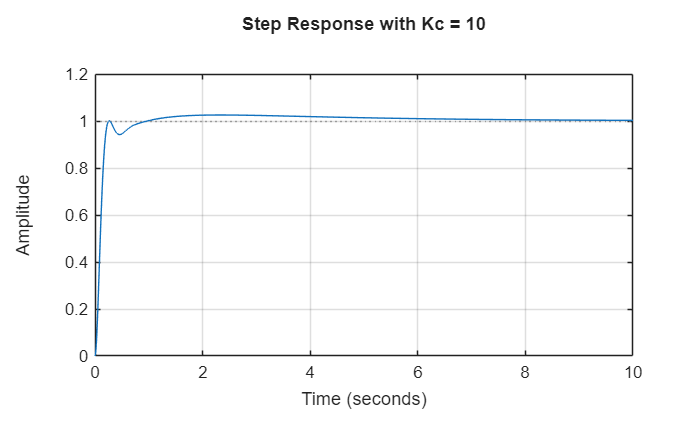

z_lead = 3; 
p_lead = 15;

C_lead_base = tf([1 z_lead], [1 p_lead]);

Kc = 10; % have tried different values o kc

C_total = C_pid * Kc * C_lead_base;

T_total = feedback(C_total * G, 1);

figure;
step(T_total);
title(['Step Response with Kc = ', num2str(Kc)]);
grid on;


info_tuned = stepinfo(T_total);
fprintf('Rise Time: %.3f s\n', info_tuned.RiseTime);

Rise Time: 0.146 s


Settling Time: 3.751 s


fprintf('Settling Time: %.3f s\n', info_tuned.SettlingTime);

#### c)

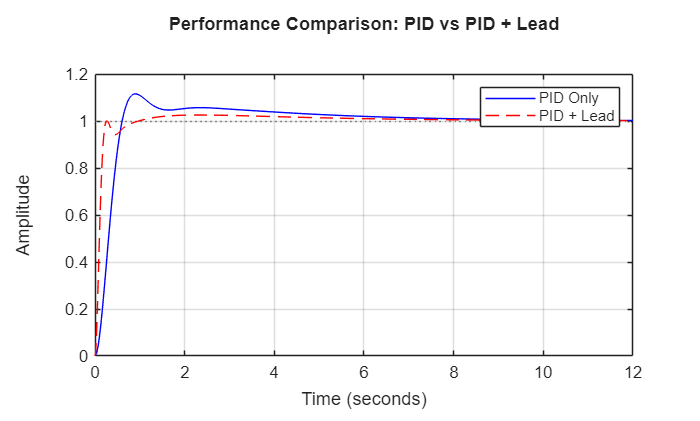

figure;
step(T_pid, 'b', T_total, 'r--');
legend('PID Only', 'PID + Lead');
title('Performance Comparison: PID vs PID + Lead');
grid on;


info_pid = stepinfo(T_pid);
info_total = stepinfo(T_total); 

fprintf('overshoot : %.3f \n' , info_pid.Overshoot)

overshoot : 11.538 


fprintf('Rise Time: %.3f s\n', info_pid.RiseTime)

Rise Time: 0.408 s


fprintf('Settling Time: %.3f s\n', info_pid.SettlingTime);

Settling Time: 5.951 s



fprintf('overshoot : %.3f \n' , info_total.Overshoot)

overshoot : 2.554 


fprintf('Rise Time: %.3f s\n', info_total.RiseTime)

Rise Time: 0.146 s


fprintf('Settling Time: %.3f s\n', info_total.SettlingTime);

Settling Time: 3.751 s


**Answer **: The lead compensator improves transient response by adding positive phase (phase lead) to the system near the crossover frequency. This increases the bandwidth, which results in a faster rise time, and generally improves the phase margin, leading to a faster settling time and better stability.

#### d)

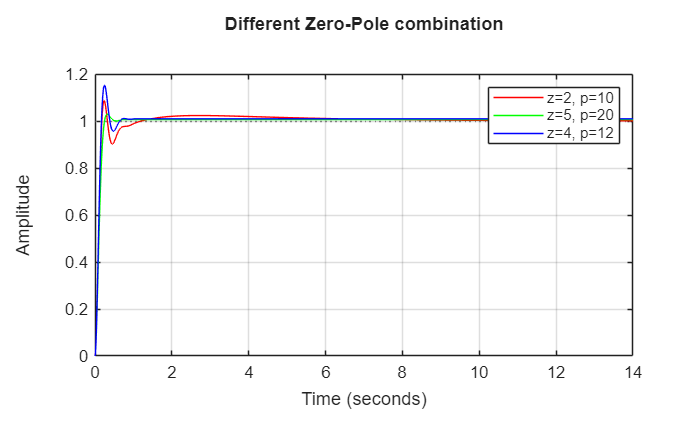

C_lead1 = 10 * (s + 2) / (s + 10); 
C_lead2 = 10 * (s + 5) / (s + 20); 
C_lead3 = 10 * (s + 4) / (s + 12);  

figure;
step(feedback(C_pid*C_lead1*G, 1), 'r'); hold on;
step(feedback(C_pid*C_lead2*G, 1), 'g');
step(feedback(C_pid*C_lead3*G, 1), 'b');
legend('z=2, p=10', 'z=5, p=20', 'z=4, p=12');
title('Different Zero-Pole combination');
grid on;

**Answer** : Moving the pole further into the left-half plane (increasing |p|) generally increases the speed of the response (bandwidth) but may require higher gain and can increase high-frequency noise.

### Problem 2:

#### a)

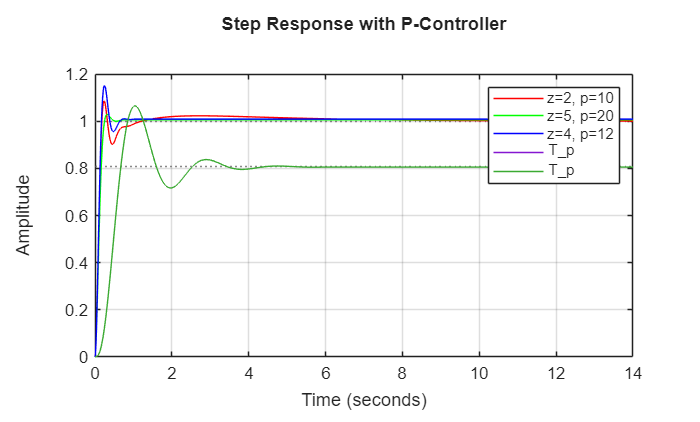

s = tf('s');
G2 = 50 / ((s+1)*(s+3)*(s+8));

Kp = 2; 
C_p = Kp;

T_p = feedback(C_p * G2, 1);

[y_p, t_p] = step(T_p);
step(T_p); grid on;
title('Step Response with P-Controller');



r_final = 1; 
y_final_p = y_p(end);
ess_p = abs(r_final - y_final_p);

fprintf('P-Controller Steady-State Error: %.4f\n', ess_p);

P-Controller Steady-State Error: 0.1920


#### b)

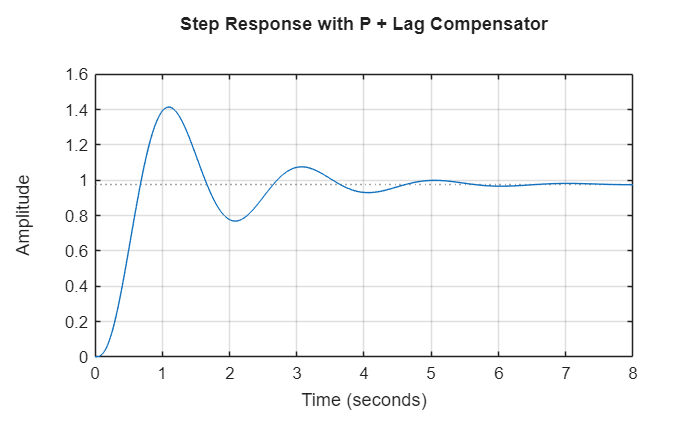

z_lag = 1;
p_lag = 0.1;
Kc_lag = 1;

C_lag = Kc_lag * (s + z_lag) / (s + p_lag); 

C_combined = C_p * C_lag;

T_lag = feedback(C_combined * G2, 1);

figure;
step(T_lag); grid on;
title('Step Response with P + Lag Compensator');

#### c)

[y_lag, t_lag] = step(T_lag);
y_final_lag = y_lag(end);
ess_lag = abs(r_final - y_final_lag); 
reduction = ((ess_p - ess_lag) / ess_p) * 100;

info_p = stepinfo(T_p);
info_lag = stepinfo(T_lag);

fprintf('Steady-State Error | %.4f | %.4f', ess_p, ess_lag);

Steady-State Error | 0.1920 | 0.0254

fprintf('Settling Time (s)  | %.2f | %.2f', info_p.SettlingTime, info_lag.SettlingTime);

Settling Time (s)  | 3.22 | 5.21

**Answer** : The lag compensator reduces steady-state error by increasing the low-frequency gain of the system without significantly changing the high-frequency response (which would affect stability).

#### d)

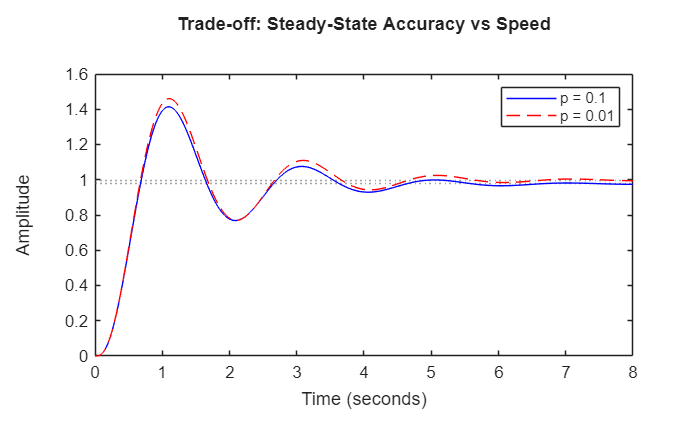

p_new = 0.01;
C_lag_slow = Kc_lag * (s + z_lag) / (s + p_new);
T_lag_slow = feedback(Kp * C_lag_slow * G2, 1);

figure;
step(T_lag, 'b', T_lag_slow, 'r--');
legend('p = 0.1', 'p = 0.01');
title('Trade-off: Steady-State Accuracy vs Speed');

**Answer** : Reducing the pole value to 0.01 further decreases steady-state error but significantly increases the settling time, making the response much slower.

#### Problem 3:

#### a)

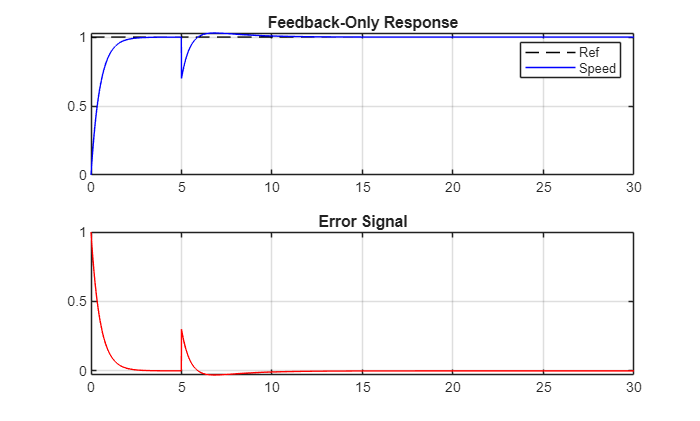

dt = 0.01;
t = 0:dt:30;
r = ones(size(t));      
d = zeros(size(t)); 
d(t>=5) = 0.3;          

Kp = 2; Ki = 1;
[num, den] = tfdata(tf(1, [1 0.5]), 'v'); 

y = zeros(size(t));
e = zeros(size(t));
e_int = 0;
u_fb = zeros(size(t));

for i = 2:length(t)
    e(i) = r(i) - y(i-1);          
    e_int = e_int + e(i)*dt;        
    u_fb(i) = Kp*e(i) + Ki*e_int;   
    
   
    dy = (-0.5*y(i-1) + u_fb(i)) * dt;
    y(i) = y(i-1) + dy - (d(i) - d(i-1)); 
end

figure;
subplot(2,1,1);
plot(t, r, 'k--', t, y, 'b');
title('Feedback-Only Response'); legend('Ref', 'Speed'); grid on;
subplot(2,1,2);
plot(t, r-y, 'r'); title('Error Signal'); grid on;

b)

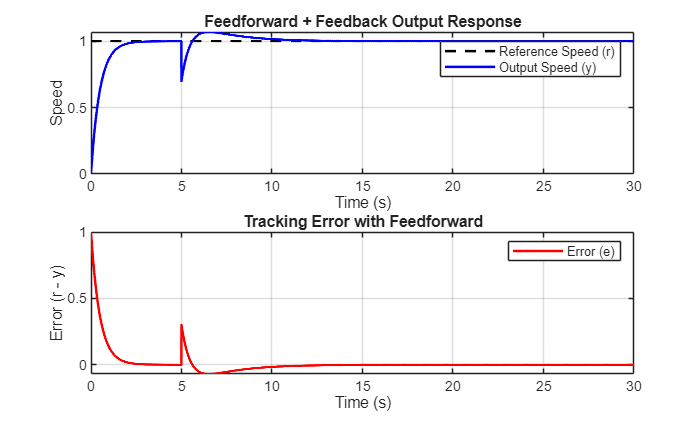

Kff = 1 / (1/0.5); 
y_ff = zeros(size(t));
e_int = 0;

for i = 2:length(t)
    e_curr = r(i) - y_ff(i-1);
    e_int = e_int + e_curr*dt;
    
    u_fb_curr = Kp*e_curr + Ki*e_int;
    u_ff_curr = Kff * 0.3 * (t(i)>=5); 
    u_total = u_fb_curr + u_ff_curr;   
    
    dy = (-0.5*y_ff(i-1) + u_total) * dt;
    y_ff(i) = y_ff(i-1) + dy - (d(i) - d(i-1));
end

e_ff_total = r - y_ff; 

figure;

subplot(2,1,1);
plot(t, r, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y_ff, 'b', 'LineWidth', 1.5);
grid on;
title('Feedforward + Feedback Output Response');
xlabel('Time (s)');
ylabel('Speed');
legend('Reference Speed (r)', 'Output Speed (y)');

subplot(2,1,2);
plot(t, e_ff_total, 'r', 'LineWidth', 1.5);
grid on;
title('Tracking Error with Feedforward');
xlabel('Time (s)');
ylabel('Error (r - y)');
legend('Error (e)');

#### c)

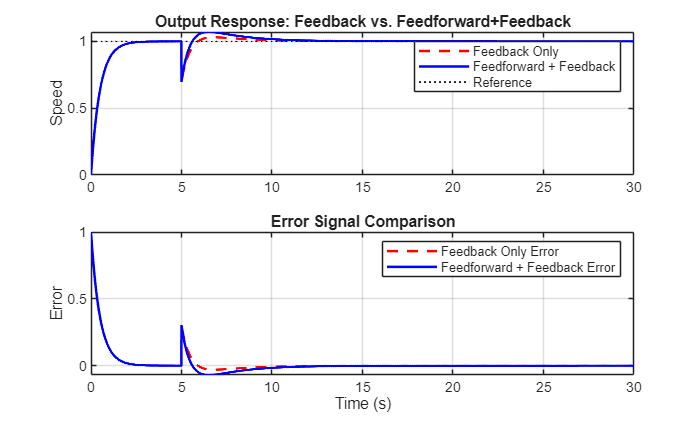

figure;
subplot(2,1,1);
plot(t, y, 'r--', 'LineWidth', 1.5); hold on; 
plot(t, y_ff, 'b', 'LineWidth', 1.5);        
plot(t, r, 'k:', 'LineWidth', 1);          
grid on;
title('Output Response: Feedback vs. Feedforward+Feedback');
ylabel('Speed');
legend('Feedback Only', 'Feedforward + Feedback', 'Reference');


subplot(2,1,2);
plot(t, r - y, 'r--', 'LineWidth', 1.5); hold on;
plot(t, r - y_ff, 'b', 'LineWidth', 1.5);
grid on;
title('Error Signal Comparison');
xlabel('Time (s)');
ylabel('Error');
legend('Feedback Only Error', 'Feedforward + Feedback Error');


max_err_fb = max(abs(r(t>5) - y(t>5)));
max_err_ff = max(abs(r(t>5) - y_ff(t>5)));

**Answer** :  Feedforward control is "proactive" because it acts on the disturbance before it affects the output. Feedback is "reactive," waiting for an error to occur before taking action.

#### **d)**

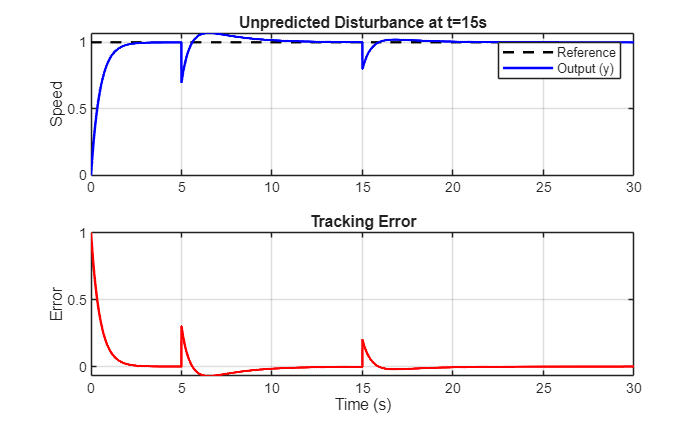

y_d = zeros(size(t));
e_d = zeros(size(t));
e_int = 0;


d1_mag = 0.3; 
d2_mag = 0.2; 

for i = 2:length(t)
   
    e_d(i) = r(i) - y_d(i-1);
    e_int = e_int + e_d(i)*dt;
    
    u_fb_curr = Kp*e_d(i) + Ki*e_int;
   
    if t(i) >= 5
        u_ff_curr = Kff * d1_mag;
    else
        u_ff_curr = 0;
    end
    
    u_total = u_fb_curr + u_ff_curr;
    
    current_dist = (t(i) >= 5)*d1_mag + (t(i) >= 15)*d2_mag;
    prev_dist = (t(i-1) >= 5)*d1_mag + (t(i-1) >= 15)*d2_mag;
    
    dy = (-0.5*y_d(i-1) + u_total) * dt;
    y_d(i) = y_d(i-1) + dy - (current_dist - prev_dist);
end

figure;
subplot(2,1,1);
plot(t, r, 'k--', t, y_d, 'b', 'LineWidth', 1.5);
grid on;
title('Unpredicted Disturbance at t=15s');
ylabel('Speed');
legend('Reference', 'Output (y)');

subplot(2,1,2);
plot(t, r - y_d, 'r', 'LineWidth', 1.5);
grid on;
title('Tracking Error');
xlabel('Time (s)');
ylabel('Error');

The PI controller detects the resulting error and gradually increases the control signal to return the speed to the reference value

 Feedforward control provides speed by handling known issues before they affect the system, while feedback control provides robustness by correcting for unknowns and modeling errors